# Comparación resultados Teóricos y Simulados Escenario 11

## Resultados de simulación sin Obstaćulos densidad baja \lambda = 1


%Promedio PDR
%Filas Densidad de menos a mas, columnas Beconing 1,2,5 y 10 Hz

PDR_MEAN(1,:) = [[0.987460024253519], [0.9835566890077614], [0.9530601608151577], [0.835220377130524]];

%Promedio CBR:
CBR_MEAN(1,:) = [[0.06434224419620226], [0.1283958646450102], [0.31419824490679], [0.5747067807830475]];

%STD PDR:
PDR_STD(1,:) = [[0.002894612324748823], [0.004128622274483598], [0.006851882018366749], [0.017663836488227898]];

%STD CBR:
CBR_STD(1,:) = [[0.0003352362990634571], [0.0006996883072163453], [0.001956066467237026], [0.009027567850368498]];

## Resultados de modelo teórico

PDR_T = base_PDR_results; %(1,:); %[0.9819 0.9775 0.9641 0.9419];
CBR_T = base_CBR_results; %(1,:);
VAP_T = [1-(1-PDR_T(:,1)).^1 1-(1-PDR_T(:,2)).^2 1-(1-PDR_T(:,3)).^3 1-(1-PDR_T(:,4)).^3]; 


## Resultados de simulación con obstáculos

% PDR Con obstáculos
PDR2_MEAN(1,:) =[[0.8817944950923657], [0.8767091047975317], [0.8329120310058258], [0.7253901621802079]];

% STD PDR:
PDR2_STD(1,:) = [[0.0024761504623913846], [0.006482423865172622], [0.007711375824828157], [0.014050960118760654]];

CBR2_MEAN(1,:) = [[0.056821857824798025], [0.1132679155877659], [0.27423807642986553], [0.5038505595206123]];

%STD CBR:
CBR2_STD(1,:) =[[0.007750999282908913], [0.015405846766808083], [0.035276861433956114], [0.06003572692488687]];


## Obtención de VAP

Sc1 = [ PDR_T(1,:) ; PDR_MEAN(1,:) ; PDR2_MEAN(1,:)];

Sc1_std = [PDR_STD(1,:) ; PDR2_STD(1,:)];

Sc1_nar = [1-(1-Sc1(:,1)).^1 1-(1-Sc1(:,2)).^2 1-(1-Sc1(:,3)).^3 1-(1-Sc1(:,4)).^3];

Sc1_nar_std = [1-(1-Sc1_std(:,1)).^1 1-(1-Sc1_std(:,2)).^2 1-(1-Sc1_std(:,3)).^3 1-(1-Sc1_std(:,4)).^3];

Sc1_c = [ CBR_T(1,:) ; CBR_MEAN(1,:) ; CBR2_MEAN(1,:)];

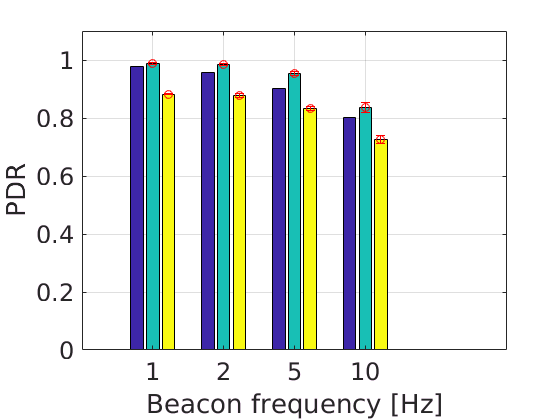

figure (1)

bar(Sc1','DisplayName','PDR_MEAN');
hold on

%title('PDR for theoretical and simulated \lambda = 1');
xlabel('Beacon frequency [Hz]');
ylabel('PDR');

x=[1 2 3 4];
%x2=[];
%x2(:,1)=x-0.27;
%x2(:,2)=x-0.1;
%x2(:,3)=x+0.1;
%x2(:,4)=x+0.27;
x2 = x + 0.22;
errorbar(x,PDR_MEAN(1,:),PDR_STD(1,:),'ro');
hold on
errorbar(x2,PDR2_MEAN(1,:),PDR2_STD(1,:),'ro');
%lgd=legend('Theory','Simulation Without Obstacles','Simulation With Obstacles','Location','SouthWest');
%lgd.FontSize = 12;
ylim([0, 1.1])
xticklabels([1 2 5 10])
set(gca,'FontSize',18)
grid on
hold off

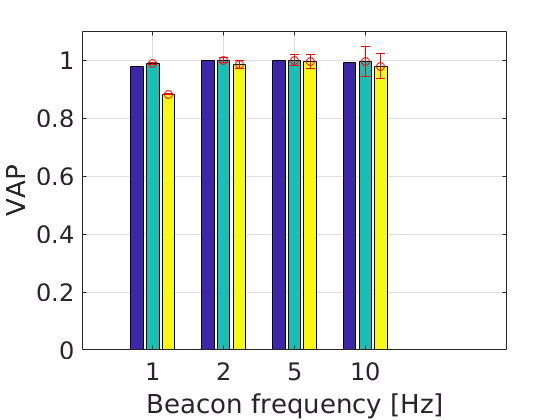

figure (2)

bar(Sc1_nar','DisplayName','PDR_MEAN');
hold on

%title('VAP for theoretical and simulated \lambda = 1');
xlabel('Beacon frequency [Hz]');
ylabel('VAP');

x=[1 2 3 4];
x2 = x + 0.22;
errorbar(x,Sc1_nar(2,:),Sc1_nar_std(1,:),'ro');
hold on
errorbar(x2,Sc1_nar(3,:),Sc1_nar_std(2,:),'ro');
%legend('Theory','Simulation Without Obstacles','Simulation With Obstacles','Location','SouthEast');
ylim([0, 1.1])
xticklabels([1 2 5 10])
set(gca,'FontSize',18)
grid on
hold off

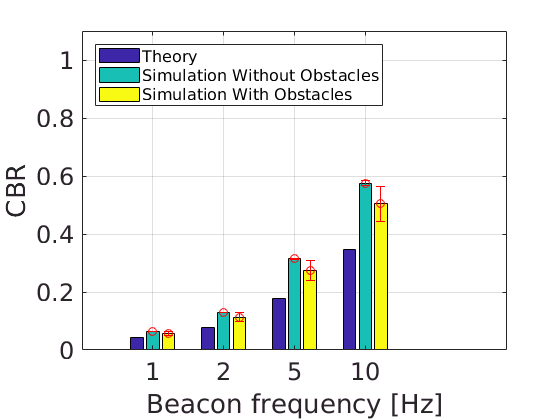


figure (3)
%bar(PDR_MEAN,'DisplayName','PDR_MEAN')
bar(Sc1_c','DisplayName','CBR_MEAN');
hold on

%title('CBR for theoretical and simulated \lambda = 1');
xlabel('Beacon frequency [Hz]');
ylabel('CBR');

errorbar(x,CBR_MEAN(1,:),CBR_STD(1,:),'ro');

hold on 
errorbar(x2,CBR2_MEAN(1,:),CBR2_STD(1,:),'ro');
lgd=legend('Theory','Simulation Without Obstacles','Simulation With Obstacles','Location','NorthWest');

ylim([0, 1.1])
xticklabels([1 2 5 10])

set(gca,'FontSize',18)
lgd.FontSize = 12;
grid on

hold off

## Resultados de simulación sin Obstaćulos densidad Alta \lambda = 2


%Promedio PDR
%Filas Densidad de menos a mas, columnas Beconing 1,2,5 y 10 Hz

PDR_MEAN(2,:) = [[0.9887457349441109], [0.9708568489218841], [0.861268230630499], [0.5189934009459257]];

%Promedio CBR:
CBR_MEAN(2,:) = [[0.11896501266589578], [0.23505330249509881], [0.5414981152228623], [0.7789497946096555]];

%STD PDR:
PDR_STD(2,:) = [[0.006162240741160844], [0.006954928395607039], [0.011366406517210301], [0.005536145578839558]];

%STD CBR:
CBR_STD(2,:) = [[0.0008624650769769522], [0.0017817884933543117], [0.005636032605108568], [0.005911770860586478]];

## Resultados de modelo teórico

%PDR_T = base_PDR_results(2,:); %[0.9819 0.9775 0.9641 0.9419];
%CBR_T = base_CBR_results(2,:);
NAR_T = [1-(1-PDR_T(2,1)).^1 1-(1-PDR_T(2,2)).^2 1-(1-PDR_T(2,3)).^3 1-(1-PDR_T(2,4)).^3]; 


## Resultados de simulación con obstáculos

% PDR Con obstáculos
PDR2_MEAN(2,:) =[[0.685425602590316], [0.6661125587755339], [0.5879666089082995], [0.4434708430723008]];

% STD PDR:
PDR2_STD(2,:) = [[0.005023359310975755], [0.004970768549817921], [0.0045792915541762865], [0.004359251856557766]];

CBR2_MEAN(2,:) =[[0.08273222620948552], [0.16257209216719398], [0.37852607640419134], [0.6394555958307185]];

%STD CBR:
CBR2_STD(2,:) =[[0.01675695448388022], [0.031186318702315464], [0.0613567883103313], [0.07605764698396371]];


## Obtención de NAR

Sc2 = [ PDR_T(2,:) ; PDR_MEAN(2,:) ; PDR2_MEAN(2,:)];

z=5.4579;

Sc2_std = [PDR_STD(2,:) ; PDR2_STD(2,:)];

Sc2_nar = [1-(1-Sc2(:,1)).^1 1-(1-Sc2(:,2)).^2 1-(1-Sc2(:,3)).^3 1-(1-Sc2(:,4)).^3];

Sc2_nar_std = [1-(1-Sc2_std(:,1)).^1 1-(1-Sc2_std(:,2)).^2 1-(1-Sc2_std(:,3)).^3 1-(1-Sc2_std(:,4)).^3];

Sc2_c = [ CBR_T(2,:) ; CBR_MEAN(2,:) ; CBR2_MEAN(2,:)];

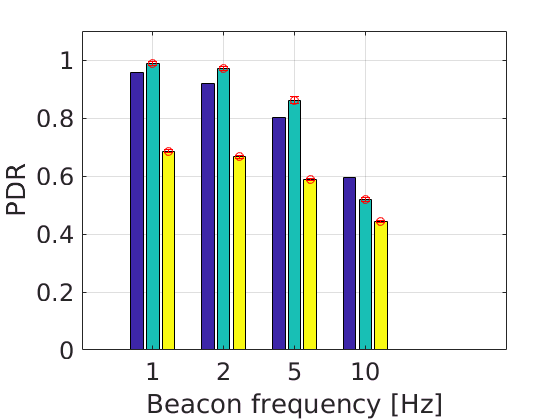

figure (1)

bar(Sc2','DisplayName','PDR_MEAN');
hold on

%title('PDR for theoretical and simulated \lambda = 2');
xlabel('Beacon frequency [Hz]');
ylabel('PDR');

x=[1 2 3 4];
%x2=[];
%x2(:,1)=x-0.27;
%x2(:,2)=x-0.1;
%x2(:,3)=x+0.1;
%x2(:,4)=x+0.27;
x2 = x + 0.22;
errorbar(x,PDR_MEAN(2,:),PDR_STD(2,:),'ro');
hold on
errorbar(x2,PDR2_MEAN(2,:),PDR2_STD(2,:),'ro');
%lgd = legend('Theory','Simulation Without Obstacles','Simulation With Obstacles','Location','SouthWest');
ylim([0, 1.1])
xticklabels([1 2 5 10])
set(gca,'FontSize',18)
grid on
%lgd.FontSize = 12;
hold off

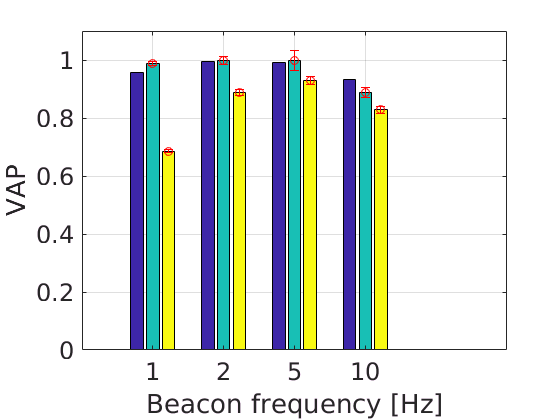

figure (2)

bar(Sc2_nar','DisplayName','PDR_MEAN');
hold on

%title('VAP for theoretical and simulated \lambda = 2');
xlabel('Beacon frequency [Hz]');
ylabel('VAP');

x=[1 2 3 4];
x2 = x + 0.22;
errorbar(x,Sc2_nar(2,:),Sc2_nar_std(1,:),'ro');
hold on
errorbar(x2,Sc2_nar(3,:),Sc2_nar_std(2,:),'ro');
%legend('Theory','Simulation Without Obstacles','Simulation With Obstacles','Location','SouthEast');
ylim([0, 1.1])
xticklabels([1 2 5 10])

set(gca,'FontSize',18)
grid on

hold off

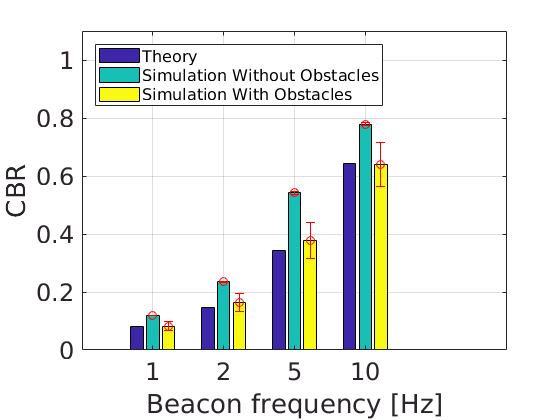


figure (3)
%bar(PDR_MEAN,'DisplayName','PDR_MEAN')
bar(Sc2_c','DisplayName','CBR_MEAN');
hold on

%title('CBR for theoretical and simulated \lambda = 2');
xlabel('Beacon frequency [Hz]');
ylabel('CBR');

errorbar(x,CBR_MEAN(2,:),CBR_STD(2,:),'ro');

hold on 
errorbar(x2,CBR2_MEAN(2,:),CBR2_STD(2,:),'ro');
lgd=legend('Theory','Simulation Without Obstacles','Simulation With Obstacles','Location','NorthWest');

ylim([0, 1.1])
xticklabels([1 2 5 10])
set(gca,'FontSize',18)
grid on
lgd.FontSize = 12;
hold off

## Resultados de simulación para diferentes reglas

%Constantes para cálculo de VAP
c_MP=[ (0.7889*29.6 + 0.7891*37.9 + 0.9444*102)/(29.6+37.9+102) ; (0.8593*40.05 + 0.9510*67.3 + 0.7563*212)/(40.05+67.3+212) ];
c_OS=[ (1*29.6 + 1*37.9 + 0.0086*102)/(29.6+37.9+102) ; (1*40.05 + 1*67.3 + 0.0210*212)/(40.05+67.3+212) ];

c2_MP = ones(2,4).*c_MP;
c2_OS = ones(2,4).*c_OS;

% OS- OnStreet
%Promedio PDR:
PDR_OS(1,:) = [[0.8289252718794436], [0.8197610181828635], [0.7766695171026157], [0.7253409480634463]];
PDR_OS(2,:) = [[0.7036095526073519], [0.6922041435218518], [0.6611707399173666], [0.6004145197472583]];
%Promedio CBR:
CBR_OS(1,:) = [[0.02970177941530486], [0.056792806914874316], [0.13437554737701482], [0.25768133649238945]];
CBR_OS(2,:) = [[0.04080302044443439], [0.07967604835338839], [0.19229551517771476], [0.3642069910465405]];

%STD PDR:
STD_PDR_OS(1,:) = [[0.002252828963299697], [0.007262957865236343], [0.00715942999852274], [0.022498504473744102]];
STD_PDR_OS(2,:) = [[0.003784906148064654], [0.0037508582858165247], [0.008050812918793155], [0.011722091688745133]];

%STD CBR:
STD_CBR_OS(1,:) = [[0.005249276758840246], [0.01033896966525306], [0.023430154259707493], [0.04309839791594865]];
STD_CBR_OS(2,:) = [[0.010122765953138801], [0.019846086943276206], [0.04646148390303935], [0.08326239538377755]];

VAP_OS = [1-(1-PDR_OS(:,1)).^1 1-(1-PDR_OS(:,2)).^2 1-(1-PDR_OS(:,3)).^3 1-(1-PDR_OS(:,4)).^3].*c2_OS; 
STD_VAP_OS = [1-(1-STD_PDR_OS(:,1)).^1 1-(1-STD_PDR_OS(:,2)).^2 1-(1-STD_PDR_OS(:,3)).^3 1-(1-STD_PDR_OS(:,4)).^3].*c2_OS; 

% MP - MovinPed

%Promedio PDR:
PDR_MP(1,:) = [[0.8850254847903454], [0.8839046859775003], [0.8528813750043313], [0.7554398211376745]];
PDR_MP(2,:) = [[0.6827917093055851], [0.6664152513588181], [0.601210533985135], [0.48182981108919554]];
%Promedio CBR:
CBR_MP(1,:) = [[0.05552146779832923], [0.10686874578935575], [0.25508228399697475], [0.4700423534012002]];
CBR_MP(2,:) = [[0.07865391482710862], [0.14500548333703198], [0.3277414711001884], [0.5666486049255937]];
%STD PDR:
STD_PDR_MP(1,:) = [[0.0036996617192151795], [0.00469423762447746], [0.007561467011805801], [0.012725221578639555]];
STD_PDR_MP(2,:) = [[0.004922361601523726], [0.005000098854029017], [0.0047996045254195515], [0.005768898401918554]];
%STD CBR:
STD_CBR_MP(1,:) = [[0.007640325334878326], [0.014585950711130582], [0.03334524897112931], [0.056802691393735234]];
STD_CBR_MP(2,:) = [[0.01672359644711641], [0.03207673826522431], [0.06957674831424748], [0.10423328868883615]];

VAP_MP = [1-(1-PDR_MP(:,1)).^1 1-(1-PDR_MP(:,2)).^2 1-(1-PDR_MP(:,3)).^3 1-(1-PDR_MP(:,4)).^3].*c2_MP; 
STD_VAP_MP = [1-(1-STD_PDR_MP(:,1)).^1 1-(1-STD_PDR_MP(:,2)).^2 1-(1-STD_PDR_MP(:,3)).^3 1-(1-STD_PDR_MP(:,4)).^3].*c2_MP; 

% Multiple TX

%Promedio PDR:
PDR_MTX(1,:) = [[0.8724960415340913], [], [], []];
PDR_MTX(2,:) = [[0.6070274653752132], [], [], []];
%Promedio CBR:
CBR_MTX(1,:) = [[0.22930960808809148], [], [], []];
CBR_MTX(2,:) = [[0.30872546713496246], [], [], []];
%STD PDR:
STD_PDR_MTX(1,:) = [[0.009880708792203558], [], [], []];
STD_PDR_MTX(2,:) = [[0.008197211012215598], [], [], []];
%STD CBR:
STD_CBR_MTX(1,:) = [[0.02950823764489281], [], [], []];
STD_CBR_MTX(2,:) = [[0.04864277292832528], [], [], []];


VAP_MTX =   [(1-(1-PDR_MTX(:,1)).^2).*(1-c2_MP) + (1-(1-PDR_MTX(:,1)).^3).*c2_MP];   %1-(1-PDR_MTX).^5.4579;
STD_VAP_MTX =  [(1-(1-STD_PDR_MTX(:,1)).^2).*(1-c2_MP) + (1-(1-STD_PDR_MTX(:,1)).^3).*c2_MP]; %1-(1-STD_PDR_MTX).^5.4579;

%Promedio PDR Teórico:
PDR_MP_T = mov_PDR_results;
%Promedio CBR Teórico:
CBR_MP_T = mov_CBR_results;
%Promedio VAP
VAP_MP_T = mov_VAP_results;

%Promedio PDR Teórico:
PDR_OS_T = street_PDR_results;
%Promedio CBR Teórico:
CBR_OS_T = street_CBR_results;
%Promedio VAP
VAP_OS_T = street_VAP_results;

%Promedio PDR Teórico:
PDR_MTX_T =tx_PDR_results;
%Promedio CBR Teórico:
CBR_MTX_T = tx_CBR_results;
%Promedio VAP
VAP_MTX_T = tx_VAP_results;


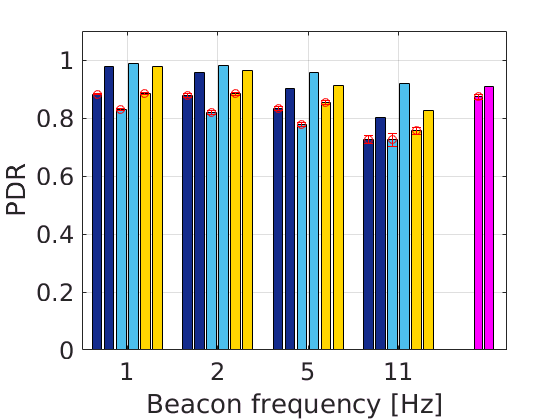

figure (4)

% Barras teórcias y simuladas
ScrD1_PDR = [PDR2_MEAN(1,:); PDR_T(1,:); PDR_OS(1,:); PDR_OS_T(1,:); PDR_MP(1,:) ; PDR_MP_T(1,:)];
b1 = bar(ScrD1_PDR','DisplayName','PDR_MEAN','FaceColor','flat');

b1(1).FaceColor=[0.08 0.17 0.55];
b1(2).FaceColor=[0.08 0.17 0.55];

b1(3).FaceColor=[0.3 0.75 0.93];
b1(4).FaceColor=[0.3 0.75 0.93];

b1(5).FaceColor=[1 0.84 0];
b1(6).FaceColor=[1 0.84 0];

hold on

%title('PDR for diferents rules \lambda = 1');
xlabel('Beacon frequency [Hz]');
ylabel('PDR');

% Errorbar 
x=[0.93 1.93 2.93 3.93];
x1 = x - 0.26;
x3 = x + 0.265;

errorbar(x1,PDR2_MEAN(1,:),PDR2_STD(1,:),'ro');
hold on
errorbar(x,PDR_OS(1,:),STD_PDR_OS(1,:),'ro');
hold on
errorbar(x3,PDR_MP(1,:),STD_PDR_MP(1,:),'ro');

%lgd = legend('Baseline With Obstacles','On Street','Movin Ped','Location','SouthEast');
%ylim([0 1])
ylim([0 1.1])
xlim([0.5 5.2])

hold on 

empty2 = [0 0 0 0 0];

ScrD1_PDR_Mtx = [empty2; empty2; [0 0 0 0 PDR_MTX(1,:)]; [0 0 0 0 PDR_MTX_T(1,1)]; empty2;  empty2 ; empty2 ];
bar(ScrD1_PDR_Mtx','DisplayName','Multiple Tx','FaceColor',[1 0 1]);
%legend('Baseline With Obstacles','On Street','Movin Ped','Multiple Tx','Location','NorthEast');

hold on
x2=[0.93 1.93 2.93 3.93 4.88];
errorbar(x2,[-1 -1 -1 -1 PDR_MTX(1,:)],[0 0 0 0 STD_PDR_MTX(1,:)],'ro','HandleVisibility','off');
grid on
%lgd.FontSize = 12;
set(gca,'FontSize',18)

xticklabels({'1', '2', '5', '11' ,'11}'})
hold off

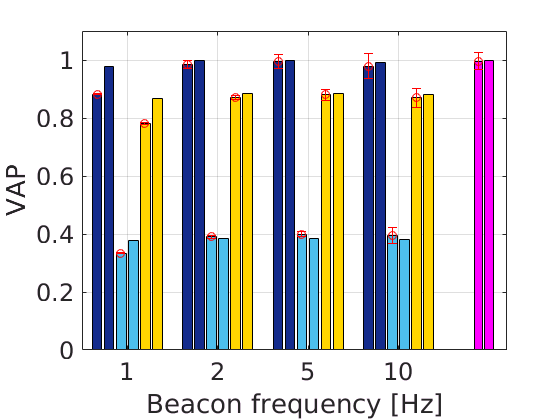

figure (5)

% Barras teórcias y simuladas
ScrD1_PDR = [Sc1_nar(3,:) ; VAP_T(1,:); VAP_OS(1,:); VAP_OS_T(1,:); VAP_MP(1,:) ; VAP_MP_T(1,:)];
b1 = bar(ScrD1_PDR','DisplayName','VAP_MEAN','FaceColor','flat');

b1(1).FaceColor=[0.08 0.17 0.55];
b1(2).FaceColor=[0.08 0.17 0.55];

b1(3).FaceColor=[0.3 0.75 0.93];
b1(4).FaceColor=[0.3 0.75 0.93];

b1(5).FaceColor=[1 0.84 0];
b1(6).FaceColor=[1 0.84 0];

hold on

%title('PDR for diferents rules \lambda = 1');
xlabel('Beacon frequency [Hz]');
ylabel('VAP');


% Errorbar 
x=[0.93 1.93 2.93 3.93];
x1 = x - 0.26;
x3 = x + 0.265;

errorbar(x1,Sc1_nar(3,:),Sc1_nar_std(2,:),'ro');
hold on
errorbar(x,VAP_OS(1,:),STD_VAP_OS(1,:),'ro');
hold on
errorbar(x3,VAP_MP(1,:),STD_VAP_MP(1,:),'ro');

%lgd = legend('Baseline With Obstacles','On Street','Movin Ped','Location','SouthEast');
%ylim([0 1])
ylim([0 1.1])
xlim([0.5 5.2])
xticklabels([1 2 5 10])
hold on 

empty2 = [0 0 0 0 0];

ScrD1_PDR_Mtx = [empty2; empty2; [0 0 0 0 VAP_MTX(1,1)]; [0 0 0 0 VAP_MTX_T(1,1)]; empty2;  empty2 ; empty2 ];
bar(ScrD1_PDR_Mtx','DisplayName','Multiple Tx','FaceColor',[1 0 1]);
%legend('Baseline With Obstacles','On Street','Movin Ped','Multiple Tx','Location','NorthEast');

hold on
x2=[0.93 1.93 2.93 3.93 4.88];
errorbar(x2,[-1 -1 -1 -1 VAP_MTX(1,1)],[0 0 0 0 STD_VAP_MTX(1,1)],'ro','HandleVisibility','off');
grid on
%lgd.FontSize = 12;
set(gca,'FontSize',18)
hold off

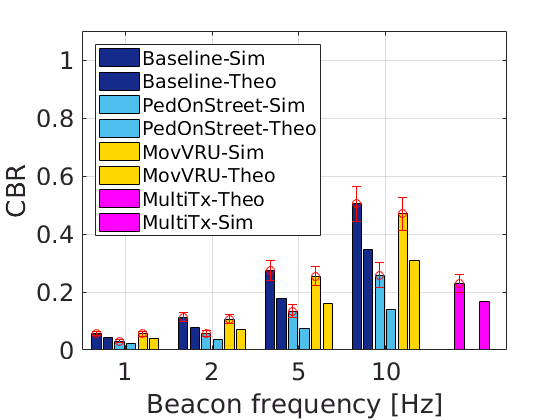

figure (6)


%%%%%%%%%%%%%%%%
% Barras teórcias y simuladas
ScrD1_PDR = [CBR2_MEAN(1,:); CBR_T(1,:); CBR_OS(1,:); CBR_OS_T(1,:); CBR_MP(1,:) ; CBR_MP_T(1,:)];
b1 = bar(ScrD1_PDR','DisplayName','PDR_MEAN','FaceColor','flat');

b1(1).FaceColor=[0.08 0.17 0.55];
b1(2).FaceColor=[0.08 0.17 0.55];

b1(3).FaceColor=[0.3 0.75 0.93];
b1(4).FaceColor=[0.3 0.75 0.93];

b1(5).FaceColor=[1 0.84 0];
b1(6).FaceColor=[1 0.84 0];

hold on

%title('PDR for diferents rules \lambda = 1');
xlabel('Beacon frequency [Hz]');
ylabel('CBR');

% Errorbar 
x=[0.93 1.93 2.93 3.93];
x1 = x - 0.26;
x3 = x + 0.265;

errorbar(x1,CBR2_MEAN(1,:),CBR2_STD(1,:),'ro','HandleVisibility','off');
hold on
errorbar(x,CBR_OS(1,:),STD_CBR_OS(1,:),'ro','HandleVisibility','off');
hold on
errorbar(x3,CBR_MP(1,:),STD_CBR_MP(1,:),'ro','HandleVisibility','off');

%lgd = legend('Baseline_{Sim}','Baseline_{Theo}','PedOnStreet_{Sim}','PedOnStreet_{Theo}','MovVRU_{Sim}','MovVRU_{Theo}','Location','NorthEast');
%lgd = legend('Baseline With Obstacles','On Street','Movin Ped','Location','SouthEast');
%ylim([0 1])
ylim([0 1.1])
xlim([0.5 5.4])
xticklabels([1 2 5 10])
hold on 

empty2 = [0 0 0 0 0];

%ScrD1_PDR_Mtx = [empty2; empty2; [0 0 0 0 CBR_MTX(1,:)]; [0 0 0 0 CBR_MTX_T(1,1)]; empty2;  empty2 ; empty2 ];
ScrD1_PDR_Mtx = [[0 0 0 0 CBR_MTX(1,:)]; [0 0 0 0 CBR_MTX_T(1,1)]];
bar(ScrD1_PDR_Mtx',0.4,'m','DisplayName','Multiple Tx','FaceColor',[1 0 1]);

hold on
x2=[0.93 1.93 2.93 3.93 4.85];
errorbar(x2,[-1 -1 -1 -1 CBR_MTX(1,:)],[0 0 0 0 STD_CBR_MTX(1,:)],'ro','HandleVisibility','off');
grid on

lgd = legend('Baseline-Sim','Baseline-Theo','PedOnStreet-Sim','PedOnStreet-Theo','MovVRU-Sim','MovVRU-Theo','MultiTx-Theo','MultiTx-Sim','Location','NorthWest');
lgd.FontSize = 14;

set(gca,'FontSize',18)


hold off

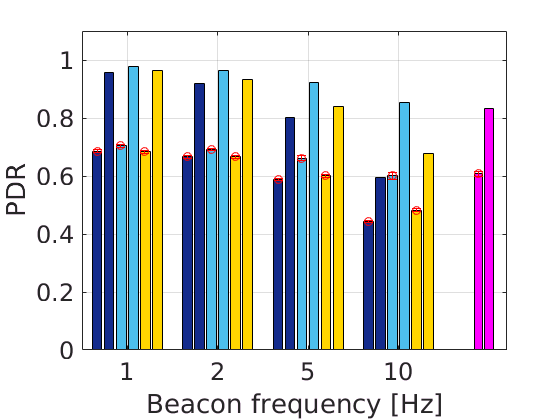

figure (7)

% Barras teórcias y simuladas
ScrD1_PDR = [PDR2_MEAN(2,:); PDR_T(2,:); PDR_OS(2,:); PDR_OS_T(2,:); PDR_MP(2,:) ; PDR_MP_T(2,:)];
b1 = bar(ScrD1_PDR','DisplayName','PDR_MEAN','FaceColor','flat');

b1(1).FaceColor=[0.08 0.17 0.55];
b1(2).FaceColor=[0.08 0.17 0.55];

b1(3).FaceColor=[0.3 0.75 0.93];
b1(4).FaceColor=[0.3 0.75 0.93];

b1(5).FaceColor=[1 0.84 0];
b1(6).FaceColor=[1 0.84 0];

hold on

%title('PDR for diferents rules \lambda = 1');
xlabel('Beacon frequency [Hz]');
ylabel('PDR');

% Errorbar 
x=[0.93 1.93 2.93 3.93];
x1 = x - 0.26;
x3 = x + 0.265;

errorbar(x1,PDR2_MEAN(2,:),PDR2_STD(2,:),'ro');
hold on
errorbar(x,PDR_OS(2,:),STD_PDR_OS(2,:),'ro');
hold on
errorbar(x3,PDR_MP(2,:),STD_PDR_MP(2,:),'ro');

%lgd = legend('Baseline With Obstacles','On Street','Movin Ped','Location','SouthEast');
%ylim([0 1])
ylim([0 1.1])
xlim([0.5 5.2])
xticklabels([1 2 5 10])
hold on 

empty2 = [0 0 0 0 0];

ScrD1_PDR_Mtx = [empty2; empty2; [0 0 0 0 PDR_MTX(2,:)]; [0 0 0 0 PDR_MTX_T(2,1)]; empty2;  empty2 ; empty2 ];
bar(ScrD1_PDR_Mtx','DisplayName','Multiple Tx','FaceColor',[1 0 1]);
%legend('Baseline With Obstacles','On Street','Movin Ped','Multiple Tx','Location','NorthEast');

hold on
x2=[0.93 1.93 2.93 3.93 4.88];
errorbar(x2,[-1 -1 -1 -1 PDR_MTX(2,:)],[0 0 0 0 STD_PDR_MTX(2,:)],'ro','HandleVisibility','off');
grid on
%lgd.FontSize = 12;
set(gca,'FontSize',18)


hold off

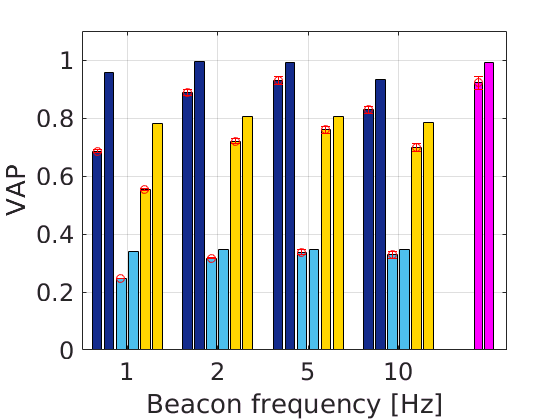

figure (8)

% Barras teórcias y simuladas
ScrD1_PDR = [Sc2_nar(3,:) ; VAP_T(2,:); VAP_OS(2,:); VAP_OS_T(2,:); VAP_MP(2,:) ; VAP_MP_T(2,:)];
b1 = bar(ScrD1_PDR','DisplayName','VAP_MEAN','FaceColor','flat');

b1(1).FaceColor=[0.08 0.17 0.55];
b1(2).FaceColor=[0.08 0.17 0.55];

b1(3).FaceColor=[0.3 0.75 0.93];
b1(4).FaceColor=[0.3 0.75 0.93];

b1(5).FaceColor=[1 0.84 0];
b1(6).FaceColor=[1 0.84 0];

hold on

%title('PDR for diferents rules \lambda = 1');
xlabel('Beacon frequency [Hz]');
ylabel('VAP');


% Errorbar 
x=[0.93 1.93 2.93 3.93];
x1 = x - 0.26;
x3 = x + 0.265;

errorbar(x1,Sc2_nar(3,:),Sc2_nar_std(2,:),'ro');
hold on
errorbar(x,VAP_OS(2,:),STD_VAP_OS(2,:),'ro');
hold on
errorbar(x3,VAP_MP(2,:),STD_VAP_MP(2,:),'ro');

%lgd = legend('Baseline With Obstacles','On Street','Movin Ped','Location','SouthEast');
%ylim([0 1])
ylim([0 1.1])
xlim([0.5 5.2])
xticklabels([1 2 5 10])
hold on 

empty2 = [0 0 0 0 0];

ScrD1_PDR_Mtx = [empty2; empty2; [0 0 0 0 VAP_MTX(2,1)]; [0 0 0 0 VAP_MTX_T(2,1)]; empty2;  empty2 ; empty2 ];
bar(ScrD1_PDR_Mtx','DisplayName','Multiple Tx','FaceColor',[1 0 1]);
%legend('Baseline With Obstacles','On Street','Movin Ped','Multiple Tx','Location','NorthEast');

hold on
x2=[0.93 1.93 2.93 3.93 4.88];
errorbar(x2,[-1 -1 -1 -1 VAP_MTX(2,1)],[0 0 0 0 STD_VAP_MTX(2,1)],'ro','HandleVisibility','off');
grid on
%lgd.FontSize = 12;
set(gca,'FontSize',18)
hold off

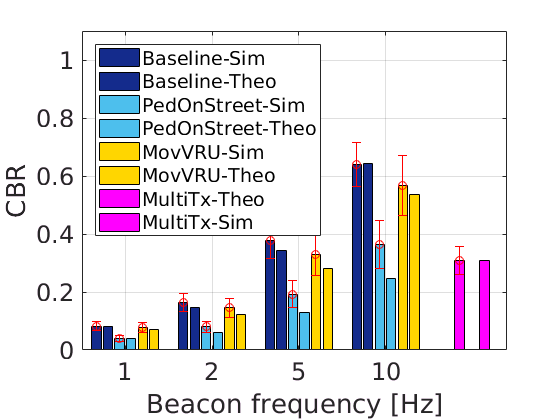

figure (9)

%%%%%%%%%%%%%%%%
% Barras teórcias y simuladas
ScrD1_PDR = [CBR2_MEAN(2,:); CBR_T(2,:); CBR_OS(2,:); CBR_OS_T(2,:); CBR_MP(2,:) ; CBR_MP_T(2,:)];
b1 = bar(ScrD1_PDR','DisplayName','PDR_MEAN','FaceColor','flat');

b1(1).FaceColor=[0.08 0.17 0.55];
b1(2).FaceColor=[0.08 0.17 0.55];

b1(3).FaceColor=[0.3 0.75 0.93];
b1(4).FaceColor=[0.3 0.75 0.93];

b1(5).FaceColor=[1 0.84 0];
b1(6).FaceColor=[1 0.84 0];

hold on

%title('PDR for diferents rules \lambda = 1');
xlabel('Beacon frequency [Hz]');
ylabel('CBR');

% Errorbar 
x=[0.93 1.93 2.93 3.93];
x1 = x - 0.26;
x3 = x + 0.265;

errorbar(x1,CBR2_MEAN(2,:),CBR2_STD(2,:),'ro','HandleVisibility','off');
hold on
errorbar(x,CBR_OS(2,:),STD_CBR_OS(2,:),'ro','HandleVisibility','off');
hold on
errorbar(x3,CBR_MP(2,:),STD_CBR_MP(2,:),'ro','HandleVisibility','off');

%lgd = legend('Baseline_{Sim}','Baseline_{Theo}','PedOnStreet_{Sim}','PedOnStreet_{Theo}','MovVRU_{Sim}','MovVRU_{Theo}','Location','NorthEast');
%lgd = legend('Baseline With Obstacles','On Street','Movin Ped','Location','SouthEast');
%ylim([0 1])
ylim([0 1.1])
xlim([0.5 5.4])
xticklabels([1 2 5 10])
hold on 

empty2 = [0 0 0 0 0];

%ScrD1_PDR_Mtx = [empty2; empty2; [0 0 0 0 CBR_MTX(1,:)]; [0 0 0 0 CBR_MTX_T(1,1)]; empty2;  empty2 ; empty2 ];
ScrD1_PDR_Mtx = [[0 0 0 0 CBR_MTX(2,1)]; [0 0 0 0 CBR_MTX_T(2,1)]];
bar(ScrD1_PDR_Mtx',0.4,'m','DisplayName','Multiple Tx','FaceColor',[1 0 1]);

hold on
x2=[0.93 1.93 2.93 3.93 4.85];
errorbar(x2,[-1 -1 -1 -1 CBR_MTX(2,:)],[0 0 0 0 STD_CBR_MTX(2,:)],'ro','HandleVisibility','off');
grid on

lgd = legend('Baseline-Sim','Baseline-Theo','PedOnStreet-Sim','PedOnStreet-Theo','MovVRU-Sim','MovVRU-Theo','MultiTx-Theo','MultiTx-Sim','Location','NorthWest');
lgd.FontSize = 14;

set(gca,'FontSize',18)


hold off